# Curves defined explicitly by functions

Single-variable calculus involves explicit functions of a single variable, like $y=x^2$, $y=\mathrm{sin}\text{ }x$, or more generally $y=f\left(x\right)$. In Calculus classes, students spend a lot of time visualizing these functions and computing related properties like derivatives and integrals.

Let's consider the exponential function, $y=e^x$, on the domain [-1,1]. First we define a set of discrete points between -1 and 1: here we use the Matlab function **linspace **to lay down 100 equally-spaced points between -1 and 1 ([see here](https://www.mathworks.com/help/matlab/ref/linspace.html)).

Next we evaluate a function called **myfunc1**, which accepts x as the input and returns y as the output.

Finally, we plot the set of points (x,y) and we see our classic exponential curve.

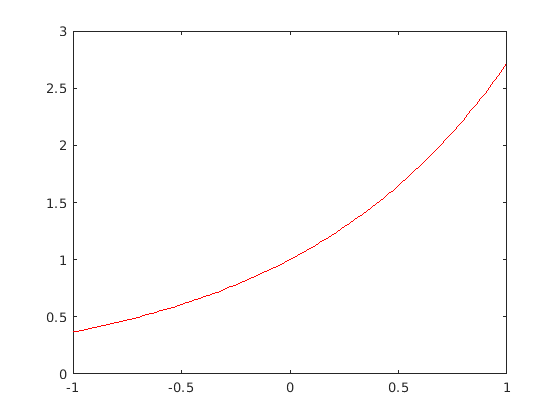

x = linspace(-1,1,100);
y = myfunc1(x);
plot(x,y,'red')

In the upper right corner of this window (the Live Editor), you'll see two icons that control the placement of figures.  Select either "Show outputs inline" or "Show outputs on the right", as you prefer.

Let's look at the previous example in more detail.  The return value from **linspace** is a matrix, which is similar to a NumPy array.  If you look at the "Workspace" (probably to the right of this window), you'll see the names **x** and **y** and their values.  The value of x is a matrix with size 1x100, which means 1 row and 100 columns, and type **double**, which means it contains double precision floating-point numbers.

The function **myfunc1** is defined at the end of this Live Script, because every function defined in a Live Script has to be defined at the end.  For your convenience, here is a copy of the definition:

`function res = myfunc1(x)`

`    res = exp(x);`

`end`

All functions begin with `function` and end with **end**.  The first line includes the name of the output variable, the name of the function, and the names of any parameters.  The output variable can have any name, but as a style choice we often use **res**.

When you assign a value to the output variable, that value becomes the function's return value.  You don't have to use a **return** statement to specify the return value.

**Exercise**: Read the documentation of the plot function, [here](https://www.mathworks.com/help/matlab/ref/plot.html), and modify the previous example to make a different color.

## Parameters

Now let's consider a more general exponential function, that depends on a parameter $\beta$, namely $y = \exp (\beta x)$. At the end of this script you will find a function **myfunc2** that accepts **x** and **beta** as input variables and returns the value of the function as an output.

Let's first evaluate it and plot it with **beta=1**, which should give us the same curve as before. 

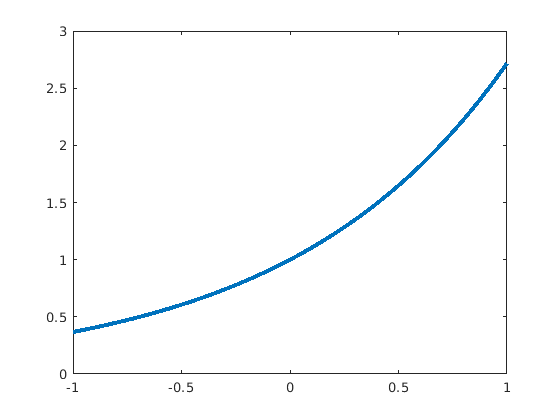

x = linspace(-1,1,100);
beta = 1;
y = myfunc2(x,beta);
plot(x,y,'LineWidth',3)

Again, myfun2 is defined at the end of this Live Script, but here is a copy: 

**function res = myfunc2(x,beta)**

**    res = exp(beta*x);**

**end**

In this example, **beta** is a scalar and **x** is a matrix, so the multiplication operator does elementwise multiplication.

**Exercise**: Read the documentation of the plot function, [here](https://www.mathworks.com/help/matlab/ref/plot.html), and modify the previous example to make the line thicker.

## Plotting multiple lines

Now we can now visualize this curve with different values of **beta**.  In order to get more than one curve in the same axes, we have to use **hold on** before we start plotting and **hold off** when we are done.

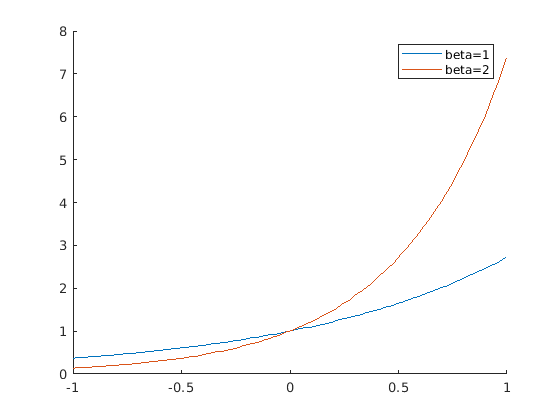

newplot; hold on
x = linspace(-1,1,100);

beta = 1;
y = myfunc2(x,beta);
plot(x,y)

beta = 2;
y = myfunc2(x,beta);
plot(x,y)

legend('beta=1', 'beta=2')
hold off

We see both curves now, and the curve with **beta=2** increases faster as we increase **x**. 

Exercise: Read the documentation of the **legend** function, [here](https://www.mathworks.com/help/matlab/ref/legend.html), and add a legend that labels each line with its value of beta.

## Sweeping a parameter

To sweep a range of values for **beta**, we can use the **colon** operator to create a matrix ([see here](https://www.mathworks.com/help/matlab/ref/colon.html)).  In the following example, the values 1, 0.2, and 2, are the first value, step size, and last value in the range:

betaRange = 1:0.2:2

betaRange =     1.0000    1.2000    1.4000    1.6000    1.8000    2.0000


Now we can use a **for** loop to iterate through the values.

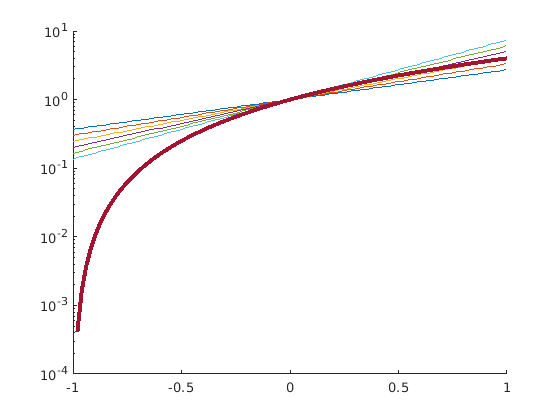

newplot; hold on
x = linspace(-1,1,100);

for beta = betaRange
    y = myfunc2(x,beta);
    plot(x,y)
end

y = myfunc3(x,1,2,1);
plot(x,y,'LineWidth',3)
yscale('log')

hold off

The result contains 11 lines, one for each value of **beta**. We conclude therefore the parameter **beta** controls the rate at which the exponential grows. For this reason, the parameter **beta** might be known as a rate constant.

**Exercise**: 

- In the space below, write a definition for a function named **myfunc3** that takes as input variables **x** and three parameters, **a**, **b**, and **c**.  It should compute the polynomial $y = ax^2 + bx + c$.  The operator you should use for exponentiation is** .^ **("dot caret"), which works elementwise.

- Call **myfunc3** to compute $y = x^2 + 2x + 1$and plot the result along with the exponential curves in the previous figure.  Change the style of the line so you can see the polynomial clearly.  Over a limited range, the difference between an exponential curve and a polynomial is not always obvious.

- The function **yscale**, defined below, let's you set the y scale to log or linear.  Call it like this:** yscale('log')**

On a log-y scale, the exponential curves should be straight lines.  The polynomial should not.

## Function definitions

As promised, here are the function definitions.

function res = myfunc1(x)
    % myfunc1   Computes exp(x)
    res = exp(x);
end

function res = myfunc2(x,beta)
    % myfunc2   Computes exp(beta x)
    res = exp(beta*x);
end

function res = myfunc3(x,a,b,c)
    % myfunc3   Computes a polynomial.
    res = a*x.^2 + b*x + c;
end

function yscale(scale)
    % yscale   Sets YScale to 'log' or 'linear'
    set(gca,'YScale', scale)
end
